# 2D Kalman Filter

Formule utili:

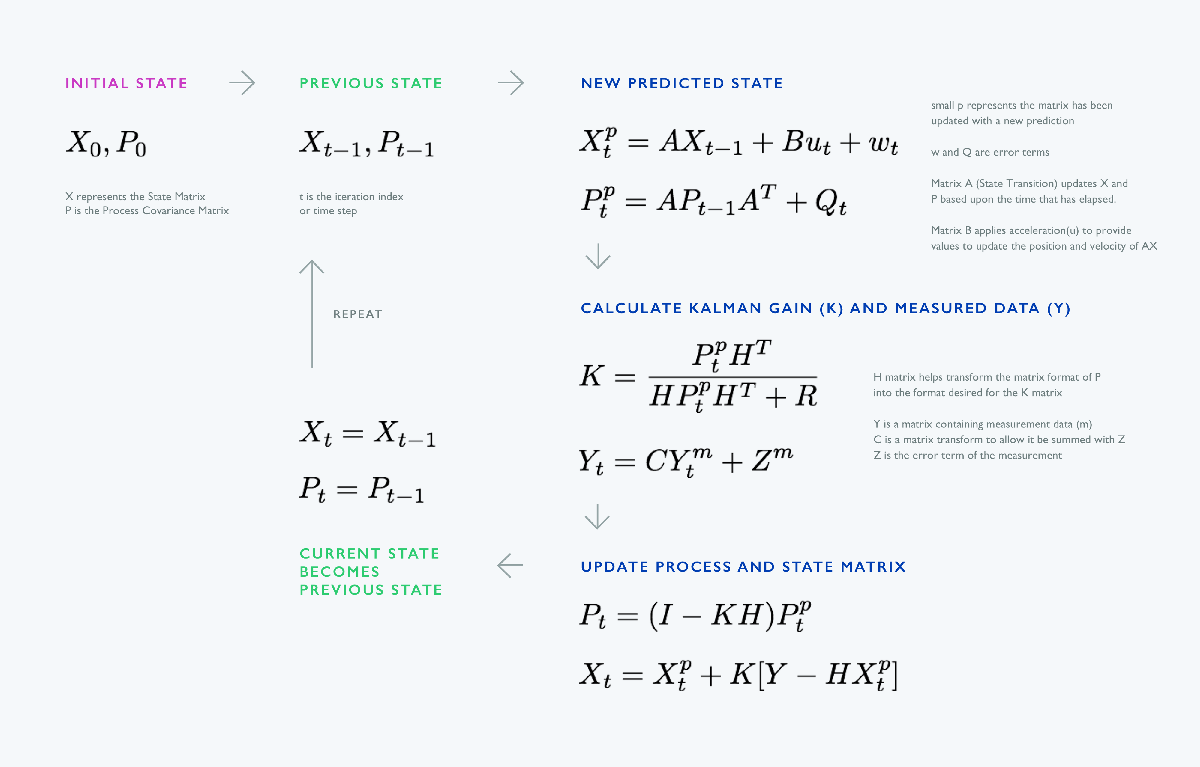

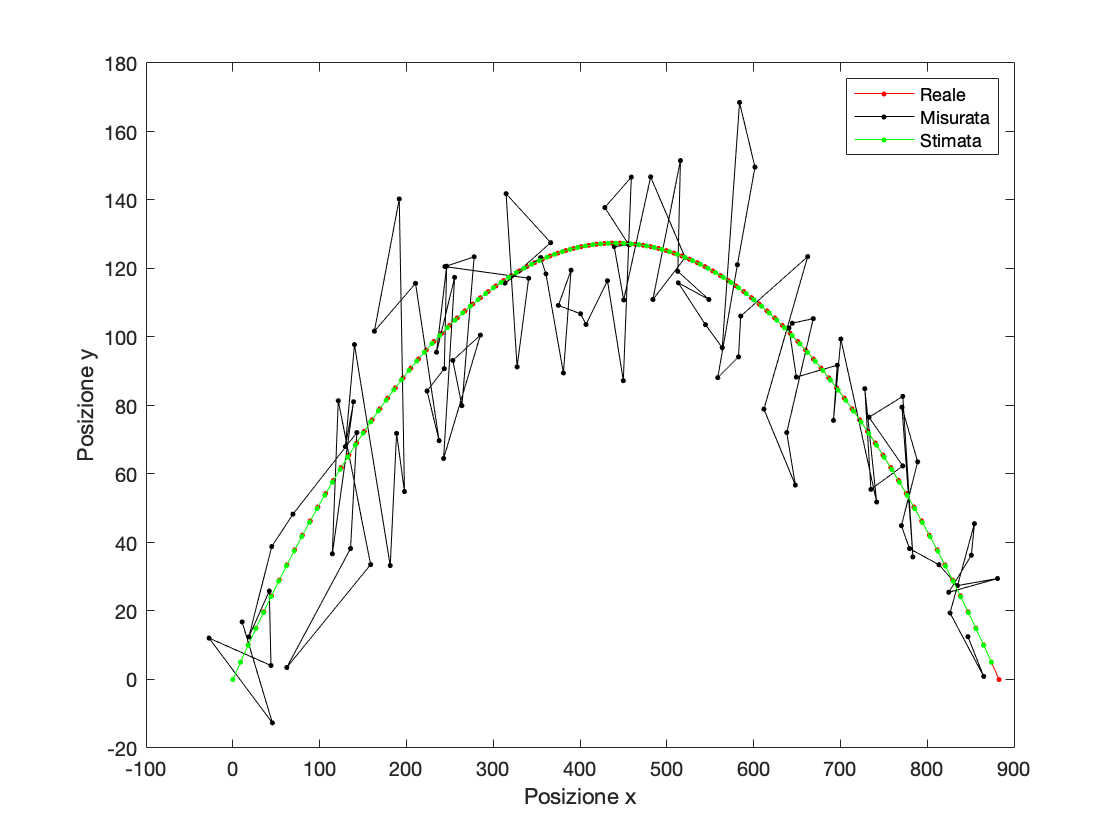

clear;
%Costanti
g = -9.81;
n = 100; %Numero di campioni della traiettoria

%Condizioni iniziali
init.px0 = 0; %Posizione
init.py0 = 0;
v0 = 100; %Velocità
theta = deg2rad(30); %Angolo
init.vx0 = v0 * cos(theta);
init.vy0 = v0 * sin(theta);

%Tempo
t0 = 0; %Istante iniziale
tf = ((2*v0*sin(theta))/-g); %Istante finale, calcolato per non simulare dopo che l'oggetto raggiunge terra
deltat = (tf-t0)/n; %"Passo di simulazione"
t = linspace(t0, tf, n);

%Traiettoria ideale
ideale.x = init.px0 + init.vx0*t;
ideale.y = init.py0 + init.vy0*t + 0.5*g*t.*t;

% Simulazione rumore di misura
rng('default'); %Init funzione di generazione casuale
stdev = 20; % Deviazione standard rumore (si suppone media=0, distribuzione normale)
misurata.x = ideale.x + stdev*randn(1,n);
misurata.y = ideale.y + stdev*randn(1,n);

% Kalman filter

A = [1 deltat 0 0;
     0 1 0 0;
     0 0 1 deltat;
     0 0 0 1]; % Matrice transizione di stato

B = [0;
     0;
     deltat^2/2;
     deltat]; % Matrice degli input

H = [1 0 0 0;
     0 0 1 0]; % Matrice di misura

u = g; % Input

p_est = [init.px0;
         init.vx0;
         init.py0;
         init.vy0];
%p_est = X0;

%Matrice di covarianza P, covarianza del processo Q ed errore di misura R
acc_noise_mag = 0.05;
sensor_noise_mag = 10;
R = sensor_noise_mag^2; %R, errore di misura, matrice di covarianza di misura
Q = acc_noise_mag^2 * B * B'; %Rumore del processo
kalman(1).P = Q; % Stima della varianza nella posizione iniziale



stimata.x = [];
stimata.y = [];
%Init
stimata.x = p_est(1);
stimata.y = p_est(3);

for i = 1:n-1
    Y = [misurata.x(i); misurata.y(i)];
    p_est = A * p_est + B * u;
    kalman(i+1).P = A * kalman(i).P * A' + Q;
    kalman(i).K = kalman(i+1).P*H'*inv(H*kalman(i+1).P*H'+R*eye(length(A)-2));
    p_est = p_est + kalman(i).K * (Y - H*p_est);
    kalman(i+1).P = ( eye(length(A)) - kalman(i).K*H ) * kalman(i+1).P; %Eye -> genera una matrice identità
    stimata.x = [stimata.x; p_est(1)];
    stimata.y = [stimata.y; p_est(3)];
end


% Grafico
plot(ideale.x,ideale.y,'r.-',misurata.x,misurata.y,'k.-', stimata.x, stimata.y,'g.-');
legend('Reale','Misurata','Stimata');
xlabel("Posizione x");
ylabel("Posizione y");

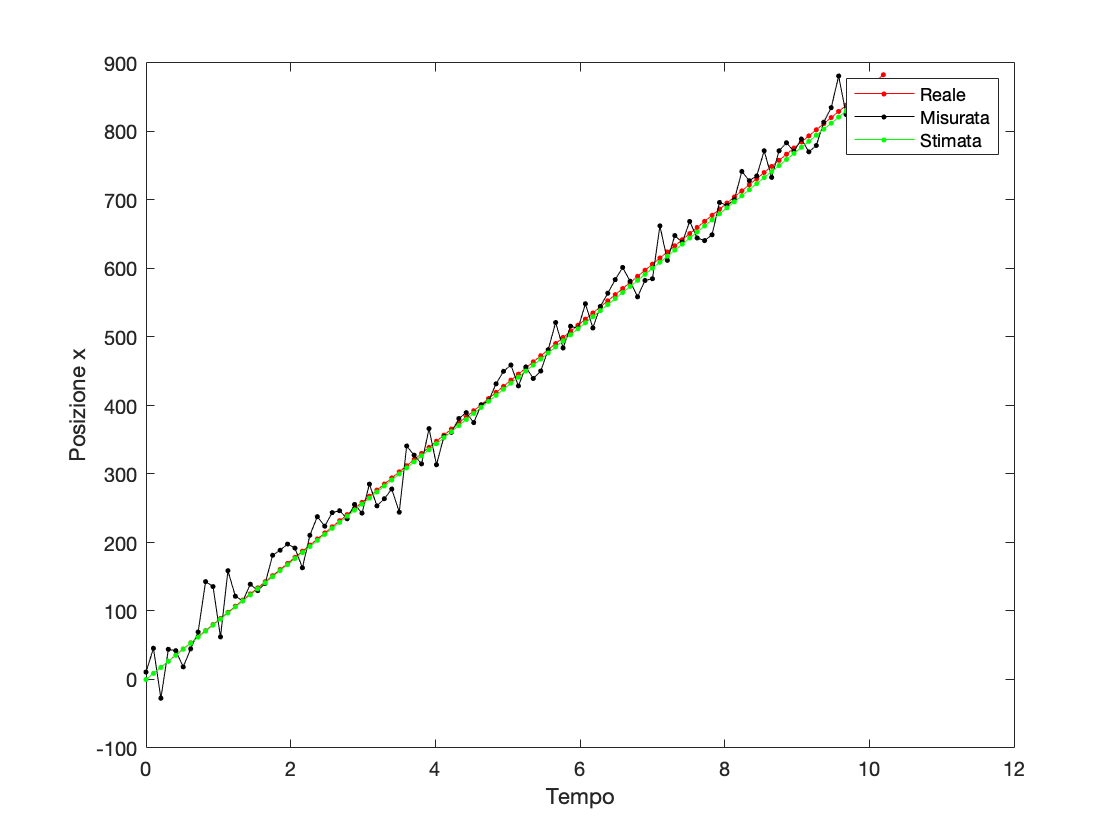

plot(t,ideale.x,'r.-',t,misurata.x,'k.-', t,stimata.x,'g.-');
legend('Reale','Misurata','Stimata');
xlabel("Tempo");
ylabel("Posizione x");

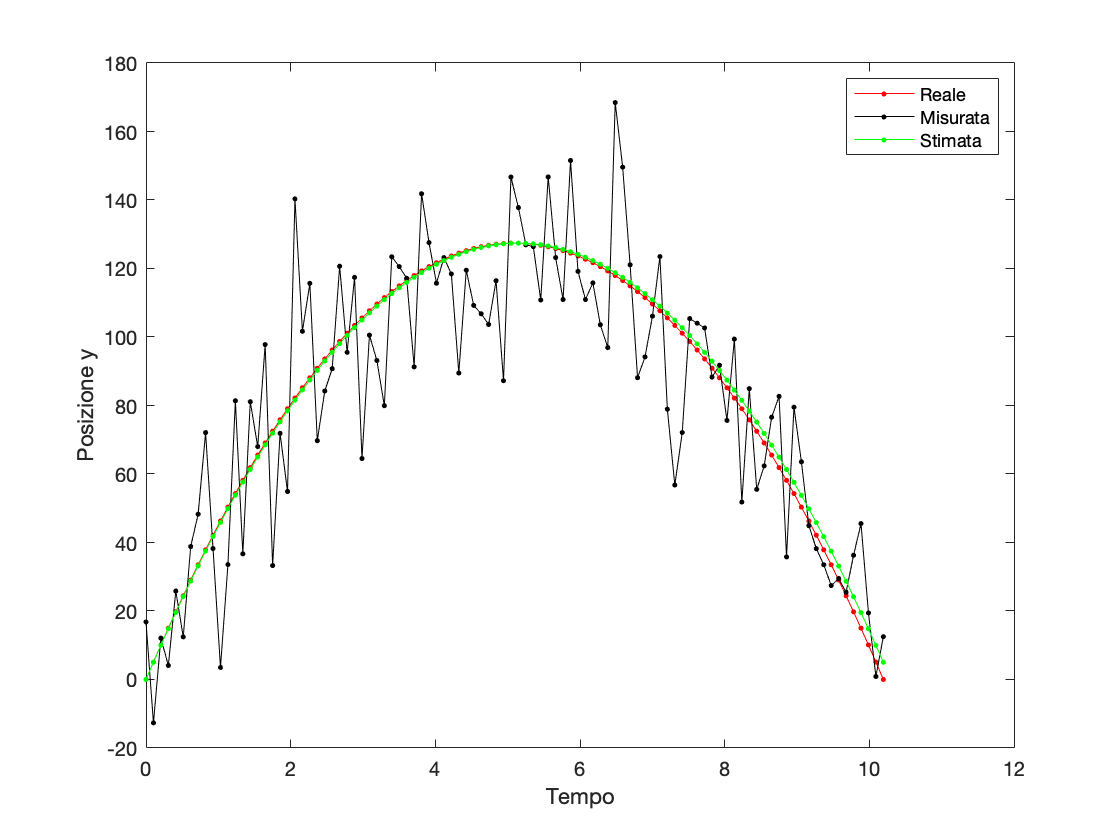

plot(t,ideale.y,'r.-',t,misurata.y,'k.-', t,stimata.y,'g.-');
legend('Reale','Misurata','Stimata');
xlabel("Tempo");
ylabel("Posizione y");